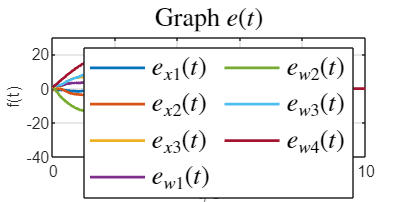

open_system('task_3_sim');
set_param('task_3_sim/x', 'VariableName', 'x')
set_param('task_3_sim/x_h', 'VariableName', 'x_h')
set_param('task_3_sim/u', 'VariableName', 'u')
set_param('task_3_sim/w_h', 'VariableName', 'w_h')
set_param('task_3_sim/w', 'VariableName', 'w')
set_param('task_3_sim/z', 'VariableName', 'z')
set_param('task_3_sim/y', 'VariableName', 'y')

K1 = [-6.5 -0.25 0.25];
L1 = [-6.3196; -36.6327; 51.9155];
L2 = [20.1333; 9.8566; 28.7566; -2.7313];
%K2 = [-41.6500 -13.4000 32.7000 -21.9000];
K2 = [-1.1923 1.4231 1.8654 -0.3077];
%K1 = [0 0 0];
%K2 = [0 0 0 0];

out = sim('task_3_sim');


figure('Position', [100 100 800 400])
plot(out.x-out.x_h,'-', 'LineWidth',1.5);
hold on
plot(out.w-out.w_h,'-', 'LineWidth',1.5);
grid()
title('Graph $e(t)$','Interpreter','latex',  'FontSize', 14)
legend('$e_{x1}(t)$', '$e_{x2}(t)$','$e_{x3}(t)$','$e_{w1}(t)$', '$e_{w2}(t)$', '$e_{w3}(t)$', '$e_{w4}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
ylim([-40 30])
hold off

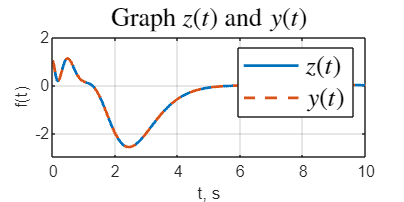



figure('Position', [100 100 800 400])
plot(out.y,'-', 'LineWidth',1.5);
hold on
plot(out.y,'--', 'LineWidth',1.5);
grid()
title('Graph $z(t)$ and $y(t)$','Interpreter','latex',  'FontSize', 14)
legend('$z(t)$', '$y(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off

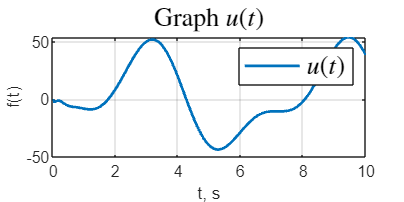



figure('Position', [100 100 800 400])
plot(out.u,'-', 'LineWidth',1.5);
grid();
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off

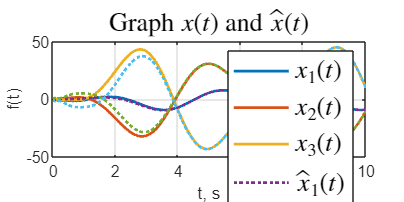



figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.x_h,':', 'LineWidth',1.5);
grid()
title('Graph $x(t)$ and $\hat{x}(t)$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$','$x_3(t)$', '$\hat{x}_1(t)$', '$\hat{x}_2(t)$', '$\hat{x}_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off

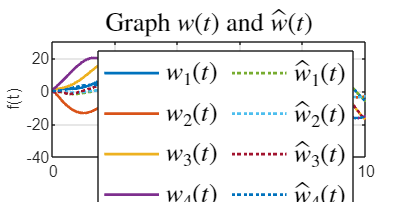



figure('Position', [100 100 800 400])
plot(out.w,'-', 'LineWidth',1.5);
hold on
plot(out.w_h,':', 'LineWidth',1.5);
grid()
title('Graph $w(t)$ and $\hat{w}(t)$','Interpreter','latex',  'FontSize', 14)
legend('$w_1(t)$', '$w_2(t)$','$w_3(t)$','$w_4(t)$', '$\hat{w}_1(t)$', '$\hat{w}_2(t)$', '$\hat{w}_3(t)$','$\hat{w}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
ylim([-40 30])
hold off



%{
figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.x_h,':', 'LineWidth',1.5);
grid()
title('Graph $z(t)$','Interpreter','latex',  'FontSize', 14)
legend('$z(t)$', '$y(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off
%}
